# Optimización en redes. Problema de árbol soporte de peso mínimo

## Resumen.

En este live script se verán los procedimientos de Matlab que resuelven el problema de árbol soporte de peso mínimo para redes no dirigidas.

## Problema de árbol soporte de peso mínimo.

Se parte del grafo (no dirigido) G=(V,E), siendo V el conjunto de vértices o nodos, se supone V={1,2,..,n} y E el conjunto de aristas. Se lee dicho grafo a partir de la lista de aristas:

s1=[1 ; 1 ;  2 ; 2 ; 2 ; 3 ; 4 ];
t1=[2 ; 3 ; 3 ; 4 ; 5 ; 5 ; 5]; 

Una vez definida la estructura de grafo, se incorporan los pesos de las aristas:

peso1 = [ 15 ; 10 ; 5 ; 7 ; 8 ; 4 ; 5 ]; 

Y se define la estructura de la red no dirigida

% R1 = graph(s1,t1,peso1); 
R1 = graph(s1,t1,peso1); 

La representación gráfica de esta red se obtiene con la función *plot* con

los siguientes argumentos:

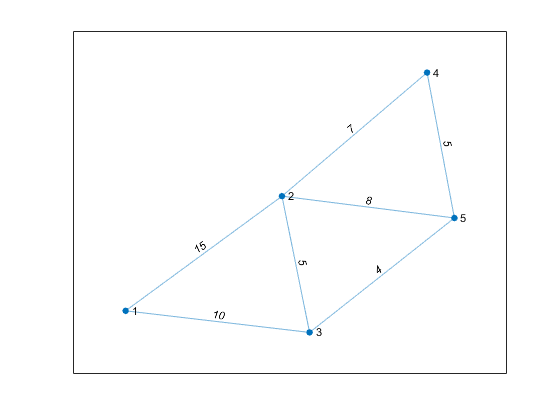

plot(R1,'Edgelabel',R1.Edges.Weight);

### Solución del problema de árbol soporte de peso mínimo

Se  utiliza la función minspantree, siendo T la estructura de la solución (el árbol soporte) y p el vector de predecesores (el valor 0 se reserva para la raíz propuesta):

[T,p]=minspantree(R1);
T

T =   graph with properties:

    Edges: [4×2 table]
    Nodes: [5×0 table]


Para acceder a la información de las aristas del árbol soporte:

T.Edges

ans = 4×2 table
    EndNodes    Weight
    ________    ______

     1    3       10  
     2    3        5  
     3    5        4  
     4    5        5  


T.Edges.Weight

ans =     10
     5
     4
     5


T.Edges.EndNodes(1,1)

ans = 1

T.Edges.EndNodes(1,2)

ans = 3

Para acceder al vector de predecesores:

p

p =      0     3     1     5     3


p(2)

ans = 3

### Visualización de la solución del problema de árbol soporte mínimo

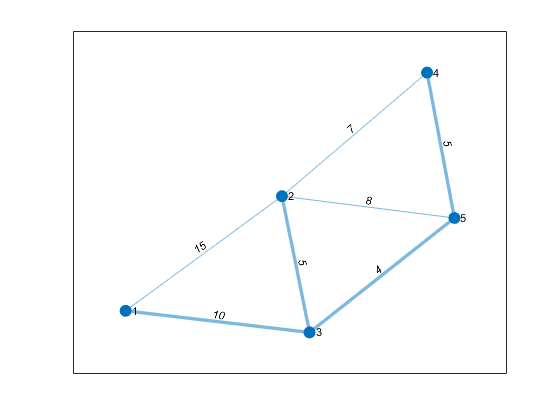

p1=plot(R1,'Edgelabel',R1.Edges.Weight); 
highlight(p1,T);  